# **2. DWT and filtering**

### **Load the signal *****ecg.mat *****(fs=356 Hz). **

Matlab has a precompiled function to calculate the DWT, *dwt.m. *

This function performs the 1-D wavelet decomposition of a signal. *CA *and *CD *vectors, contain the coefficients of approximation and detail, respectively.

Keep in mind that, if fs is the sampling frequency, CA contains the components from 0 to fs/4, while CD contains the components from fs/4 to fs/2. 

Remind that both factors are down-sampled with respect to the original signal by a factor 2. Use help command to study the function. 		

To decompose the signal at different levels, the function must be applied repeatedly, by decomposing the CA obtained at the previous level. To reconstruct the original signal you can apply the function *idwt.m*. 

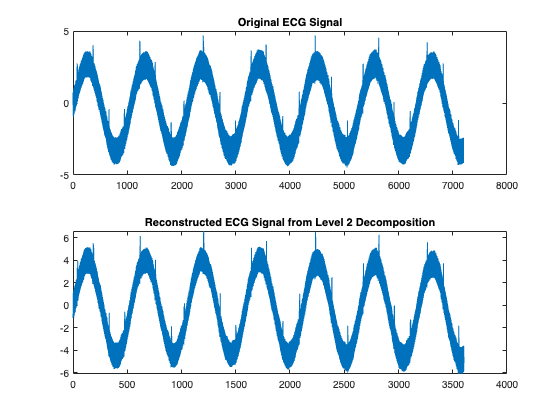

% Load the ECG signal
load('ecg.mat');
fs = 356; % Hz

% First level decomposition
[CA1, CD1] = dwt(ecg, 'db4');

% Second level decomposition
[CA2, CD2] = dwt(CA1, 'db4');

% Reconstruct signal from second level
reconstructed_ecg = idwt(CA2, CD2, 'db4');

% Plot original and reconstructed signal to compare
figure;
subplot(2, 1, 1);
plot(ecg);
title('Original ECG Signal');
subplot(2, 1, 2);
plot(reconstructed_ecg);
title('Reconstructed ECG Signal from Level 2 Decomposition');

**Differences between original and reconstructed signal:**

- **Detail Loss**: The most significant difference typically lies in the loss of finer details. The high-frequency components that capture sharp transitions and fine details in the original signal may not be fully captured in the reconstructed signal.

- **Noise Reduction**: If the original signal contains noise, the reconstructed signal may have less noise. This is due to the high-frequency noise being represented in the detail coefficients, which are not fully used in the reconstruction or are thresholded if denoising processes are applied.

- **Edge Artifacts**: Sometimes, wavelet reconstruction can introduce artifacts, especially near the edges of the signal. These can occur due to the way boundaries are handled in the wavelet transform.

### **Filter the ecg signal using the *****dwt_signal.m *****function **

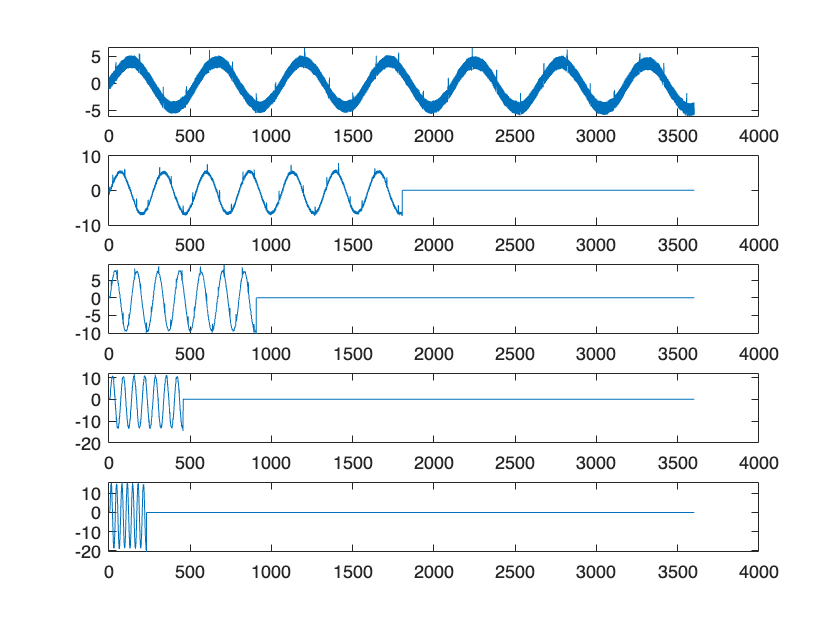

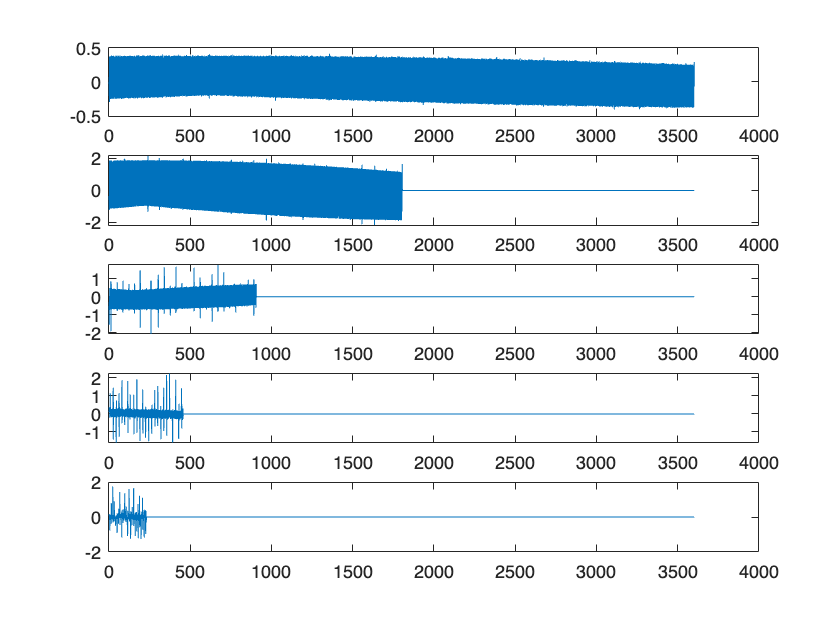

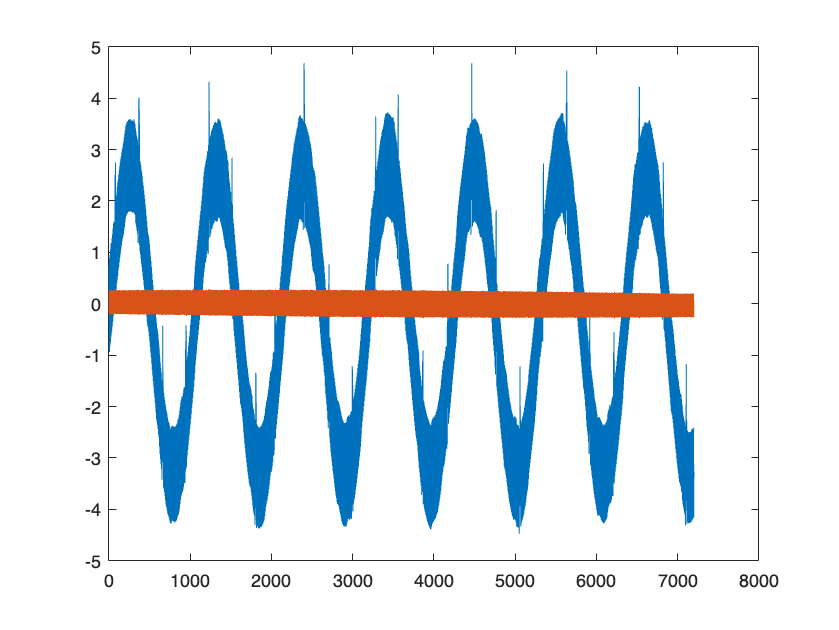

% Load the ECG signal
load('ecg.mat');
fs = 356; % Hz

% Define parameters for DWT
level = 5;  % Number of levels of decomposition
wname = 'db4';  % Wavelet type, e.g., Daubechies 4

% Filter type:
% 'A' - Use approximation coefficients for filtering (low-pass filter effect)
% 'D' - Use detail coefficients for filtering (high-pass filter effect)
filter_type = 'A';  % Change to 'D' as needed

% Call the DWT signal function
[CA, CD, reconstructed_signal] = dwt_signal1(ecg', level, wname, filter_type);

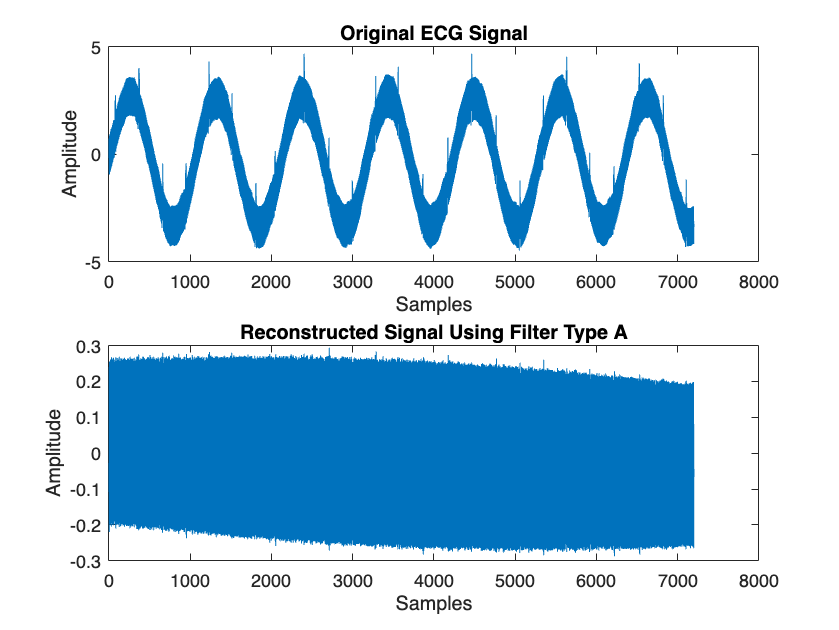


% Plot the original and the filtered signals for comparison
figure;
subplot(2,1,1);
plot(ecg);
title('Original ECG Signal');
xlabel('Samples');
ylabel('Amplitude');

subplot(2,1,2);
plot(reconstructed_signal);
title(['Reconstructed Signal Using Filter Type ', filter_type]);
xlabel('Samples');
ylabel('Amplitude');

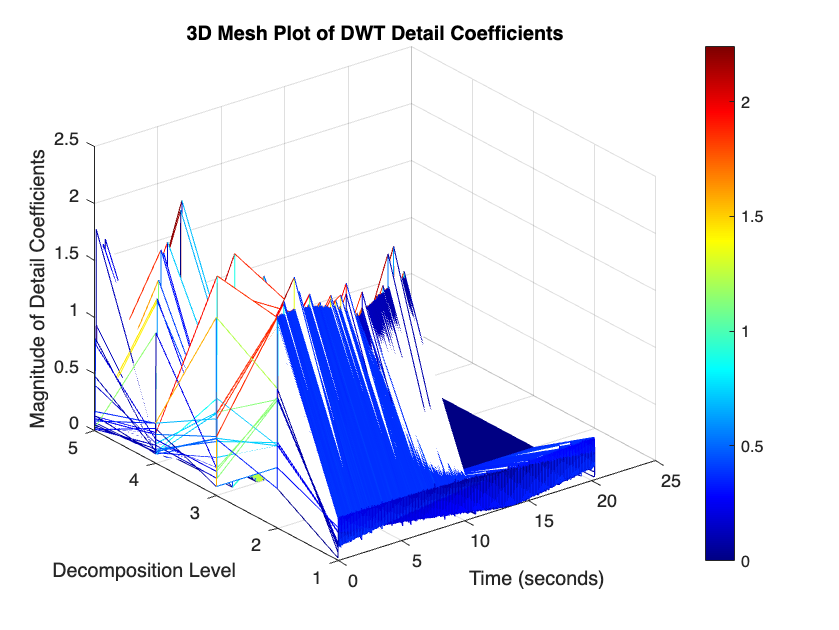


% plot of DWT in Time-Frequency domain

% Assuming 'CD' contains detail coefficients from your dwt_signal1 function

% Determine the number of decomposition levels and the length of coefficients
[numLevels, coeffLength] = size(CD);

% Create a time vector for the coefficients
% This assumes all levels of detail coefficients are the same length as the first level
timeVector = linspace(0, length(ecg) / fs, coeffLength);

% Create a levels vector representing each decomposition level
levelsVector = 1:numLevels;

% Create a meshgrid for plotting
[TimeGrid, LevelGrid] = meshgrid(timeVector, levelsVector);

% Plotting the mesh of the detail coefficients
figure;
mesh(TimeGrid, LevelGrid, abs(CD));
xlabel('Time (seconds)');
ylabel('Decomposition Level');
zlabel('Magnitude of Detail Coefficients');
title('3D Mesh Plot of DWT Detail Coefficients');
colormap jet;  % Use a color map that visually stands out
colorbar;  % Show a color bar indicating the magnitude scale

To assess the quality of frequency resolution at low and high frequencies, consider

how well-defined the contours are along the frequency axis of the components: at low

frequencies, the contours are better defined, indicating that the frequency resolution

is superior in these areas.

Alternatively, the same information can be observed from the isolevel contour plot, where

the peaks at high frequencies are taller than those at low frequencies because the frequency

resolution improves at lower frequencies.

For temporal resolution, it can be observed (from the mesh or contour plot) that there are

more points over time at higher frequencies, indicating that the temporal resolution is

better in these areas.

**Explanation **

- **Frequency Resolution**:

- **Low Frequencies**: Typically, lower frequencies can be observed with greater precision in wavelet analysis, meaning their contours (the boundaries of frequency components on a plot) are more defined. This is correctly noted in your original comment. This means that lower frequencies can be isolated better, showing clearer distinctions between different frequency components.

- **High Frequencies**: Although the original comment seems to suggest that high frequencies show higher peaks because of improved resolution, this is somewhat misleading. Generally, high-frequency components can indeed show higher peak amplitudes in certain analyses, but this doesn't necessarily mean better frequency resolution. In wavelet transforms, higher frequencies are represented with less scale resolution but more temporal resolution.

- **Temporal Resolution**:

- **High Frequencies**: It's accurate that higher frequencies in wavelet analysis are associated with better temporal resolution. This is because higher frequency components of the wavelet transform are sampled more finely over time, allowing more detailed temporal variations to be captured. This finer temporal sampling results in more data points over time at these frequencies.

- **Visualization Tools**:

- **Mesh and Contour Plots**: These plots are useful for visualizing how well different frequencies and their temporal variations are captured. Mesh plots provide a 3D surface view, while contour plots can highlight constant levels of frequency components, making it easier to discern the resolution quality across the spectrum.

**Additional Notes**

- When interpreting these plots, it's crucial to understand the characteristics of the wavelet used, as different wavelets can provide varying levels of resolution based on their shape and the length of their support.

- The description now correctly emphasizes the differences in resolution along frequency and time axes and correctly aligns these characteristics with typical outcomes of wavelet analysis.